# Image and Video Processing - Task 3

## Detection of Circular objects by edge detection and Hough Transform

Daniel Kuknyo - [Y80L35]

### Read and setup

To preprocess a Gaussian filter is run on the image, then a Canny algorithm to detect all the edges.

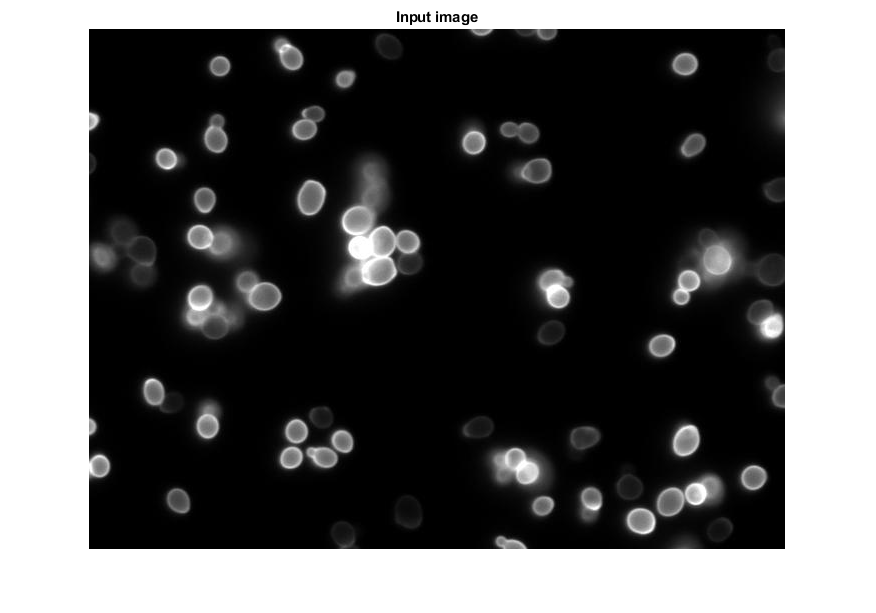

clear all; clc; close all;

% Parameters
blur_sigma = 5; % Distribution parameter for the Gaussian blur
threshold = 25; % Threshold for the accumulator array
circle_radii = [8, 25]; % Circle radius range
imname = 'cells.png';

img = im2gray(imread(imname));
img_blur = imgaussfilt(img, blur_sigma);
img_edge = edge(img_blur, 'canny');

figure;
imshow(img);
title('Input image')

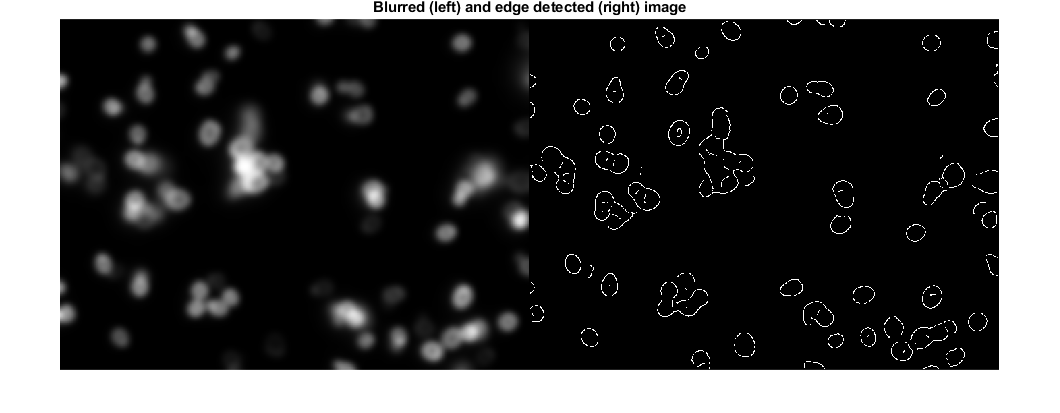

figure;
imshowpair(img_blur, img_edge, 'montage');
title('Blurred (left) and edge detected (right) image');

### Running Hough transform

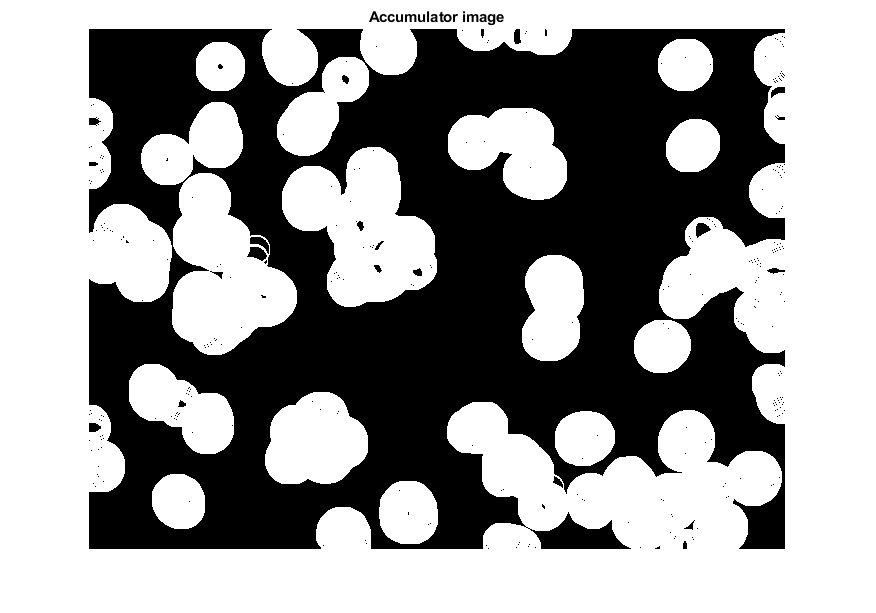

[centers, radii] = imfindcircles(img_edge, circle_radii);
r = mean(radii, 1); % Finding the optimal radius to look for

A = zeros(size(img_edge)); % Accumulator image
for cx = 1:size(img_edge, 1)
    for cy = 1:size(img_edge, 2)
        th = 0:pi/50:2*pi;
        xunit = r * cos(th) + cx;
        yunit = r * sin(th) + cy;
        coordmat = [xunit; yunit];
        
        % Check for legitimate coordinates
        % When circle is not fully in the image
        legit_coords = [];
        for i = 1:size(coordmat, 2)
            if(coordmat(1, i) >= 1 && coordmat(2, i) >= 1)
                if(coordmat(1, i) <= size(img_edge, 1) && ...
                        coordmat(2, i) <= size(img_edge, 2))
                    legit_coords = [legit_coords floor(coordmat(:, i))];
                end
            end
        end

        % Counting support for the circle
        s = 0;
        for j = 1:size(legit_coords, 2)
            px = legit_coords(1, j);
            py = legit_coords(2, j);
            val = img_edge(px, py);
%             B(px, py) = 255;
            if(val == 1)
                s = s + 1;
            end
        end
        A(cx, cy) = s;
    end
end

figure;
imshow(A);
title('Accumulator image');

### Thresholding the Hough transform

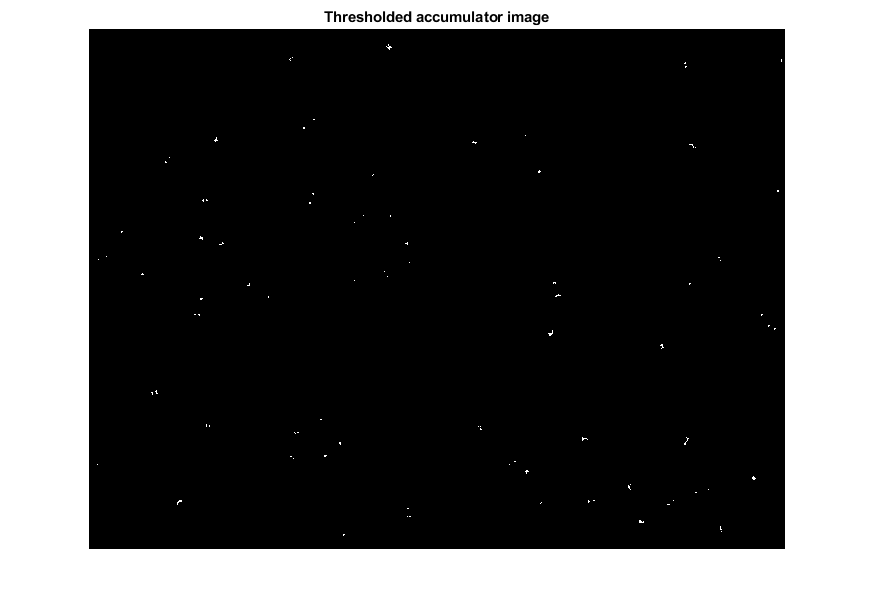

for i = 1:size(A, 1)
    for j = 1:size(A, 2)
        if(A(i,j) <= threshold)
            A(i,j) = 0;
        end
    end
end

figure;
imshow(A);
title('Thresholded accumulator image');

### Assembling the final output image

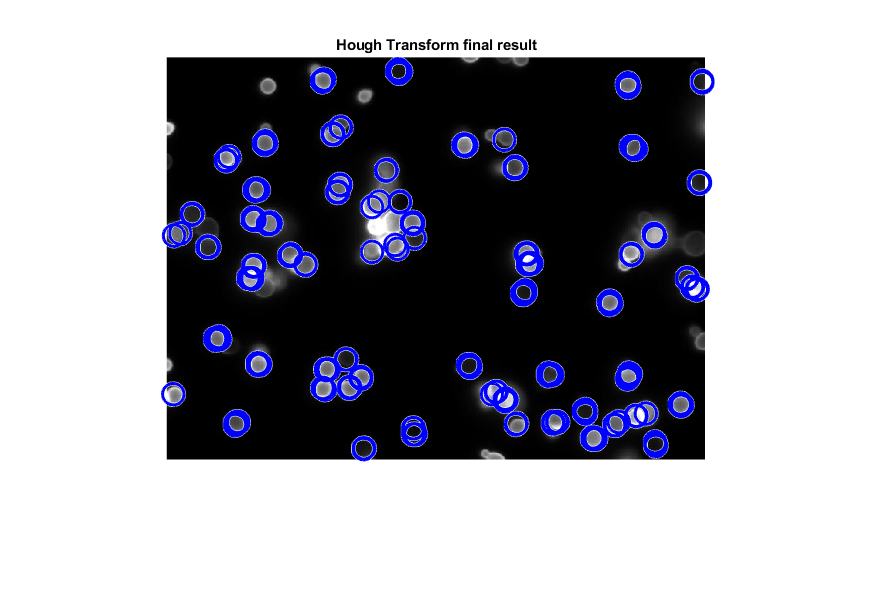

locations = [];
radii = [];
for i = 1:size(A, 1)
    for j = 1:size(A, 2)
        if(A(i, j) > 0)
            locations = [locations; [j i]];
            radii = [radii; r];
        end
    end
end

fig = figure; 
hold on;
imshow(img);
viscircles(locations, radii, 'Color', 'b');
title('Hough Transform final result');
saveas(fig, strcat('Hough_', imname));
hold off;